if ~exist('Option','var')
    disp("Option struct does not exist, creating one")
    addpath(genpath(codedefine()));
    Option = option.defaults(); 
else
    disp("Option struct already exists, using that")
    Option = option.setdefaults(Option);
    disp("Option struct is: ")
    disp(Option)
end

Option struct already exists, using that


Option struct is: 


                           animal: 'JS17'
                     samplingRate: []
                     spikeBinSize: 0.0250
                          winSize: [-0.5000 0.5000]
          positiveDerivativeCheck: [0 0.1500]
       equalWindowsAcrossPatterns: 1
            quantileToMakeWindows: 0.8500
       thetadelta_outlierQuantile: [0 0.9950]
                   spikeShiftSize: 0.0100
                    timesPerTrial: 100
                       sourceArea: "CA1"
                 waysOfPartitions: 2
                    singleControl: 0
               oldControlBehavior: 0
                     lowerControl: 1
                    binsToMatchFR: 20
           preProcess_FilterLowFR: 1
    preProcess_matchingDiscreteFR: 1
        preProcess_gaussianFilter: 5
                preProcess_zscore: 1
                     numPartition: 40
                  dimCompAnalysis: 5
                       stablePerf: 0.9000
                        generateH: "fromSpectra  fromRipTimes"
                   

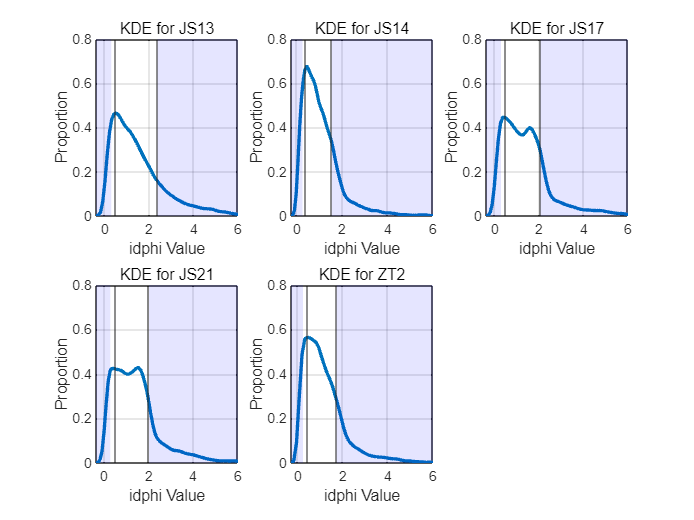

Starting lookup for JS	Table with fields: time, vel, lindist, tperf_timewise, region, traj, trajbound, rewarded, X, Y, day, epoch

Converting to table:  000%  |                                          | 0/16 [00:00:00<Inf:NaN:NaN, Inf it/s]Throwing out times greater than 2 seconds away
Done with addToBehavior ... took 9.1014 seconds
Starting lookup for JS	Table with fields: time, vel, lindist, tperf_timewise, region, traj, trajbound, rewarded, X, Y, day, epoch

Converting to table:  000%  |                                          | 0/16 [00:00:00<Inf:NaN:NaN, Inf it/s]Throwing out times greater than 2 seconds away
Done with addToBehavior ... took 8.943 seconds
Starting lookup for JS	Table with fields: time, vel, lindist, tperf_timewise, region, traj, trajbound, rewarded, X, Y, day, epoch

Converting to table:  000%  |                                          | 0/16 [00:00:00<Inf:NaN:NaN, Inf it/s]Throwing out times greater than 2 seconds away
Done with addToBehavior ... took 9.9947 s


% 动物名称的列表
animals = {'JS13','JS14','JS17','JS21','ZT2'}; % 添加您所有的动物名字

% 定义子图的行数和列数。例如，如果您有8只动物，可能希望有2行4列的子图。
nRows = 2; 
nCols = 3;

figure; % 打开新的图形窗口

for i = 1:5

% Windowing parameters
Option.spikeBinSize = 0.025;
Option.timesPerTrial = 100;
Option.winSize = [-0.5 0.5];
Option.preProcess_zscore = true;
Option.numPartition = 40;
Option.animal = animals{i};
Option.jpecc.cvnum = 10;




%%%%%%%%%%%%%%%% DISPLAY OUR OPTIONS TO USER %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%{
if isequal(Option.loadifexists, false) && ...
    exist(store.gethash(Option) + ".mat", 'file')
    disp("Loading from file: " + store.gethash(Option) + ".mat")
    m = matfile(store.gethash(Option) + ".mat");
    % m = matfile("bef0923.mat", "Writable", true);
    disp("Loaded variables: ")
    Events             = util.matfile.getdefault(m, 'Events', []);
    Spk                = util.matfile.getdefault(m, 'Spk', []);
    Patterns           = util.matfile.getdefault(m, 'Patterns', []);
    Patterns_overall   = util.matfile.getdefault(m, 'Patterns_overall', []);
    Components         = util.matfile.getdefault(m, 'Components', []);
    Components_overall = util.matfile.getdefault(m, 'Components_overall', []);
    Option             = util.matfile.getdefault(m, 'Option', []);
    disp("...done")
else
%}
    %%%%%%%%%%%%%%%% OBTAIN EVENT MATRICES    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Getting behavior
    [behavior, thrown_out_times] = table.behavior.lookup(Option.animal, ...
                                                         []);
    %{
    
    Events = events.initEvents();
    % Test case 1: TriggerOn when velocity (vel) exceeds a certain threshold
    Events = events.generateFromBehavior(behavior, {'rewardTimes'}, ...
        Events, 'triggerOnValues', {1}, ...
                'triggerOnVarnames', {'rewardTimes'}, ...
                'windowParameters',Option.winSize);
    Events = events.generateFromBehavior(behavior, {'rewardTimes'}, ...
        Events, 'triggerOffValues', {1}, ...
                'triggerOffVarnames', {'rewardTimes'}, ...
                'windowParameters',Option.winSize);
    qselect = @(x) (x.idphi > quantile(x.idphi, 0.95)) & ((x.lindist > 0.1) & (x.lindist < 0.9));
    Events = events.generateFromBehavior(behavior, {'idphi'}, ...
        Events, 'triggerVarLambdas', {qselect}, ...
                'triggerVars', {'idphi'}, ...
                'maxWindows', 2000, ...
                'windowParameters',Option.winSize);
    qselect2 = @(x) (x.idphi < quantile(x.idphi, 0.05)) & ((x.lindist > 0.1) & (x.lindist < 0.9));
    Events = events.generateFromBehavior(behavior, {'idphi'}, ...
        Events, 'triggerVarLambdas', {qselect2}, ...
                'triggerVars', {'idphi'}, ...
                'maxWindows', 2000, ...
                'windowParameters',Option.winSize);
    % Characterize events
    %figure; events.plot_events(Events, 'rewardTimes');
    % figure; events.plotIEI(Events, 'NumBins', 1000);
    %figure; events.plotCrossIEI(Events, 'NumBins', 1000, 'layout', 'matrix');
    Option.nPatternAndControl = numel(Events.cellOfWindows);
    Option.patternNames = ["rewardOn", "rewardOff","idphi","idphi_low"];
    
    %}

% 假设的数据
plot_beh = behavior((behavior.vel > quantile(behavior.vel, 0.4)) & ((behavior.lindist > (0.25 + behavior.trajbound*0.1)) & (behavior.lindist < (0.5 + behavior.trajbound*0.1))),:);


% 核密度估计
[f, xi] = ksdensity(plot_beh.idphi);

% 归一化核密度以得到比例
delta_xi = xi(2) - xi(1); % xi的步长
f = f / (sum(f) * delta_xi);

% 在子图中绘制曲线
subplot(nRows, nCols, i);
plot(xi, f, 'LineWidth', 2); % 使用线宽为2的线条绘制

xlim([min(xi) 6]);
ylim([0 0.8]);

xline(quantile(plot_beh.idphi, 0.8))
xline(quantile(plot_beh.idphi, 0.2))

% 添加阴影
hold on
h1 = area([min(xi) quantile(plot_beh.idphi, 0.1)], [0.8 0.8], 'FaceColor', 'blue', "EdgeColor",'none');
h2 = area([quantile(plot_beh.idphi, 0.8) max(xi)], [0.8 0.8], 'FaceColor', 'blue', "EdgeColor",'none');
alpha(h1, 0.1);
alpha(h2, 0.1);

xlabel('idphi Value'); % x轴标签
ylabel('Proportion');  % y轴标签
title(['KDE for ' animals{i}]); % 图表标题，包括动物的名称
grid on; % 显示网格
end


%saveas(gcf, "F:\ComSub\Figures\multi_animals\KDE OF IdPhi.pdf");

unique(behavior.trajall)

plot_beh = behavior
%(((behavior.lindist > 0.1) & (behavior.lindist < 0.9)),:)

plot_beh = behavior(((behavior.vel > quantile(behavior.vel, 0.4))& ((behavior.lindist > 0.1) & (behavior.lindist < 0.9)) & (behavior.trajbound ==1)),:);

plot_beh = behavior((abs(behavior.vel) > 3),:)

if ~exist('Option','var')
    disp("Option struct does not exist, creating one")
    addpath(genpath(codedefine()));
    Option = option.defaults(); 
else
    disp("Option struct already exists, using that")
    Option = option.setdefaults(Option);
    disp("Option struct is: ")
    disp(Option)
end

% 动物名称的列表
animals = {'JS13','KL8','JS14', "JS15","JS17","JS21","ZT2","ER1"}; % 添加您所有的动物名字


for i = 1:length(animals)

% Windowing parameters
Option.spikeBinSize = 0.025;
Option.timesPerTrial = 100;
Option.winSize = [-0.5 0.5];
Option.preProcess_zscore = true;
Option.numPartition = 40;
Option.animal = animals{i};
Option.jpecc.cvnum = 10;




%%%%%%%%%%%%%%%% DISPLAY OUR OPTIONS TO USER %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%{
if isequal(Option.loadifexists, false) && ...
    exist(store.gethash(Option) + ".mat", 'file')
    disp("Loading from file: " + store.gethash(Option) + ".mat")
    m = matfile(store.gethash(Option) + ".mat");
    % m = matfile("bef0923.mat", "Writable", true);
    disp("Loaded variables: ")
    Events             = util.matfile.getdefault(m, 'Events', []);
    Spk                = util.matfile.getdefault(m, 'Spk', []);
    Patterns           = util.matfile.getdefault(m, 'Patterns', []);
    Patterns_overall   = util.matfile.getdefault(m, 'Patterns_overall', []);
    Components         = util.matfile.getdefault(m, 'Components', []);
    Components_overall = util.matfile.getdefault(m, 'Components_overall', []);
    Option             = util.matfile.getdefault(m, 'Option', []);
    disp("...done")
else
%}
    %%%%%%%%%%%%%%%% OBTAIN EVENT MATRICES    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Getting behavior
    [behavior, ~] = table.behavior.lookup(Option.animal, ...
                                                         []);
    %{
    
    Events = events.initEvents();
    % Test case 1: TriggerOn when velocity (vel) exceeds a certain threshold
    Events = events.generateFromBehavior(behavior, {'rewardTimes'}, ...
        Events, 'triggerOnValues', {1}, ...
                'triggerOnVarnames', {'rewardTimes'}, ...
                'windowParameters',Option.winSize);
    Events = events.generateFromBehavior(behavior, {'rewardTimes'}, ...
        Events, 'triggerOffValues', {1}, ...
                'triggerOffVarnames', {'rewardTimes'}, ...
                'windowParameters',Option.winSize);
    qselect = @(x) (x.idphi > quantile(x.idphi, 0.95)) & ((x.lindist > 0.1) & (x.lindist < 0.9));
    Events = events.generateFromBehavior(behavior, {'idphi'}, ...
        Events, 'triggerVarLambdas', {qselect}, ...
                'triggerVars', {'idphi'}, ...
                'maxWindows', 2000, ...
                'windowParameters',Option.winSize);
    qselect2 = @(x) (x.idphi < quantile(x.idphi, 0.05)) & ((x.lindist > 0.1) & (x.lindist < 0.9));
    Events = events.generateFromBehavior(behavior, {'idphi'}, ...
        Events, 'triggerVarLambdas', {qselect2}, ...
                'triggerVars', {'idphi'}, ...
                'maxWindows', 2000, ...
                'windowParameters',Option.winSize);
    % Characterize events
    %figure; events.plot_events(Events, 'rewardTimes');
    % figure; events.plotIEI(Events, 'NumBins', 1000);
    %figure; events.plotCrossIEI(Events, 'NumBins', 1000, 'layout', 'matrix');
    Option.nPatternAndControl = numel(Events.cellOfWindows);
    Option.patternNames = ["rewardOn", "rewardOff","idphi","idphi_low"];
    
    %}
unique_epochs = unique(behavior.epoch);

for j = 1:length(unique_epochs)
    current_epoch = unique_epochs(j);


% 假设的数据
plot_beh = behavior(((behavior.epoch == current_epoch) & (behavior.lindist > 0.1) & (behavior.lindist < 0.9) & (behavior.vel > quantile(behavior.vel, 0.4) & (behavior.trajbound == 0))),:);

% 在子图中绘制曲线
figure
% 绘制idphi与lindist的散点图
scatter(plot_beh.lindist, plot_beh.idphi, 'b.'); % 使用蓝色点表示
xlabel('lindist');
ylabel('idphi');
title(animals{i} + "--" + current_epoch);
hold on;

% 计算idphi的0.95和0.05分位数
q95 = quantile(plot_beh.idphi, 0.9);
q05 = quantile(plot_beh.idphi, 0.1);

% 在图上添加0.95和0.05分位数线
line([min(plot_beh.lindist), max(plot_beh.lindist)], [q95, q95], 'Color', 'r', 'LineStyle', '--'); % 使用红色虚线表示0.95分位数
line([min(plot_beh.lindist), max(plot_beh.lindist)], [q05, q05], 'Color', 'g', 'LineStyle', '--'); % 使用绿色虚线表示0.05分位数

legend('Data', '0.9 Quantile', '0.1 Quantile');

end
end


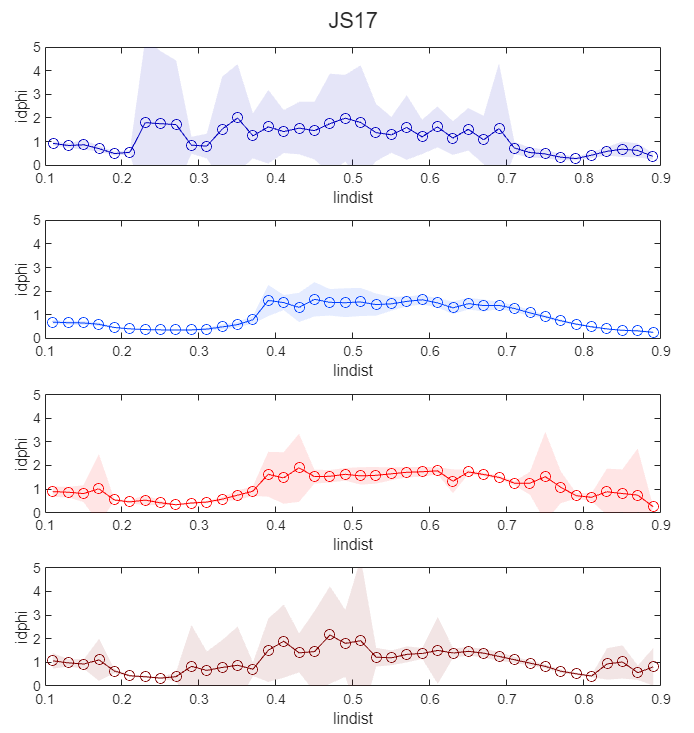

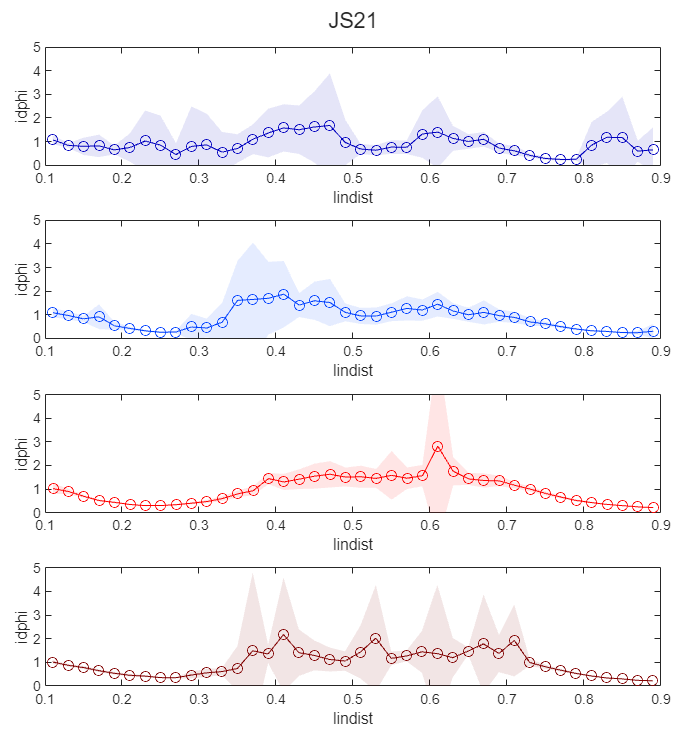

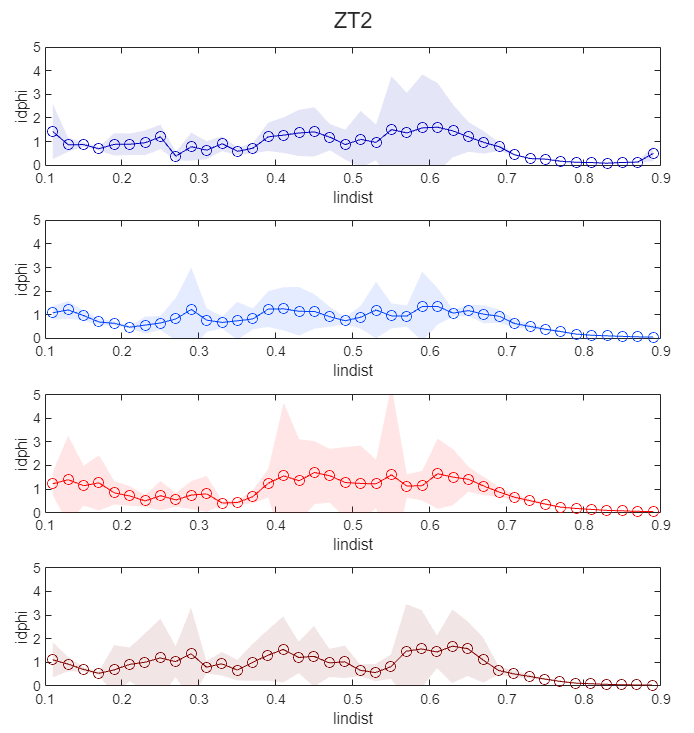

if ~exist('Option','var')
    disp("Option struct does not exist, creating one")
    addpath(genpath(codedefine()));
    Option = option.defaults(); 
else
    disp("Option struct already exists, using that")
    Option = option.setdefaults(Option);
    disp("Option struct is: ")
    disp(Option)
end

% 动物名称的列表
animals = {'JS13','KL8','JS14', 'JS15','JS17','JS21','ZT2','ER1'};

% 为epoch创建颜色映射
color_map = jet(16);
color_map = [color_map(1,:); color_map(3,:); color_map(14,:); color_map(16,:)];

for i = 1:length(animals)
    % Windowing parameters
    Option.spikeBinSize = 0.025;
    Option.timesPerTrial = 100;
    Option.winSize = [-0.5 0.5];
    Option.preProcess_zscore = true;
    Option.numPartition = 40;
    Option.animal = animals{i};
    Option.jpecc.cvnum = 10;

    [behavior, ~] = table.behavior.lookup(Option.animal, []);
    
    fig = figure('Position', [100, 100, 800, 2000]); % Increase the height of the figure
    t = tiledlayout(4, 1, 'Padding', 'compact', 'TileSpacing', 'compact'); % Adjust the spacing between tiles
    title(t, animals{i});
    
    unique_epochs = {[2, 4], [6, 8], [10, 12], [14, 16]}; 

    for j = 1:4
        current_epochs = unique_epochs{j};   
        plot_beh = behavior((ismember(behavior.epoch, current_epochs) & (behavior.lindist > 0.1) & (behavior.lindist < 0.9) & (behavior.vel > quantile(behavior.vel, 0.4) & (behavior.trajbound == 0))), :);

        edges = linspace(min(plot_beh.lindist), max(plot_beh.lindist), 41);
        [N,~,bin] = histcounts(plot_beh.lindist, edges);
        
        median_vals = zeros(1, 40);
        var_vals = zeros(1, 40);
        bin_centers = (edges(1:end-1) + edges(2:end)) / 2;

        for b = 1:40
            ids_in_bin = find(bin == b);
            bin_idphis = plot_beh.idphi(ids_in_bin);
            median_vals(b) = mean(bin_idphis);
            var_vals(b) = var(bin_idphis);
        end
        
        current_color = color_map(j, :);
        nexttile
        plot(bin_centers, median_vals, '-o', 'DisplayName', ['Epochs: ' num2str(current_epochs(1)) ' & ' num2str(current_epochs(2))], 'Color', current_color);
        hold on
        fill([bin_centers, fliplr(bin_centers)], [median_vals+var_vals, fliplr(median_vals-var_vals)], current_color, 'FaceAlpha', 0.1, 'EdgeColor', 'none');
        
        % Set y-axis limits
        ylim([0 5]);
        xlabel('lindist');
        ylabel('idphi');
    end
    saveas(fig, ['F:\ComSub\Figures\multi_animals\' animals{i} '_idphi.png']);
end

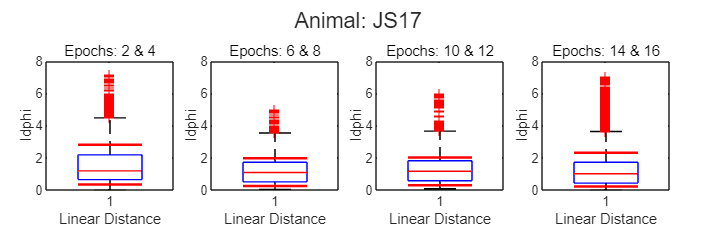

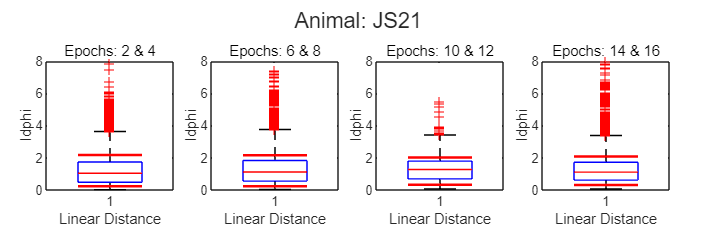

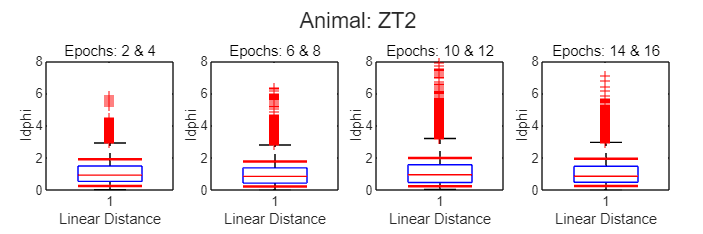

if ~exist('Option','var')
    disp("Option struct does not exist, creating one")
    addpath(genpath(codedefine()));
    Option = option.defaults(); 
else
    disp("Option struct already exists, using that")
    Option = option.setdefaults(Option);
    disp("Option struct is: ")
    disp(Option)
end

animals = {'JS13','KL8','JS14', 'JS15','JS17','JS21','ZT2','ER1'};
combined_epochs = {[2, 4], [6, 8], [10, 12], [14, 16]};

for i = 1:length(animals)
    % Windowing parameters
    Option.spikeBinSize = 0.025;
    Option.timesPerTrial = 100;
    Option.winSize = [-0.5 0.5];
    Option.preProcess_zscore = true;
    Option.numPartition = 40;
    Option.animal = animals{i};
    Option.jpecc.cvnum = 10;

    [behavior, ~] = table.behavior.lookup(Option.animal, []);
    
    fig = figure('Position', [100, 100, 1200, 400]); % [left, bottom, width, height]
    t = tiledlayout(1, length(combined_epochs), 'TileSpacing', 'compact', 'Padding', 'compact'); % 横向并列的子图

    for j = 1:length(combined_epochs)
        % 获取当前组合epoch的数据
        current_epochs = combined_epochs{j};  
        current_data = behavior((ismember(behavior.epoch,current_epochs) & (behavior.lindist > 0.25) & (behavior.lindist < 0.55) & (behavior.vel > quantile(behavior.vel, 0.425) & (behavior.trajbound == 0))),:);

        idphis = current_data.idphi;
        
        nexttile
        boxplot(idphis, 'Widths', 0.5);
        hold on;
        % 计算10%和85%的分位数
        q10 = quantile(idphis, 0.10);
        q85 = quantile(idphis, 0.85);
        % 在图上绘制这两个分位数
        plot([0.75, 1.25], [q10, q10], '-r', 'LineWidth', 1.5);
        plot([0.75, 1.25], [q85, q85], '-r', 'LineWidth', 1.5);
        
        title(['Epochs: ' num2str(combined_epochs{j}(1)) ' & ' num2str(combined_epochs{j}(2))]);
        xlabel('Linear Distance');
        ylabel('Idphi');
        ylim([0 8]);
    end
    
    sgtitle(['Animal: ' animals{i}]);
    
    % 保存图形为图片文件
    saveas(fig, ['F:\ComSub\Figures\multi_animals\' animals{i} '_boxplot.png']);
end

plot_beh = behavior(((behavior.lindist > (0.2 + behavior.trajbound*0.2)) & (behavior.lindist < (0.5 + behavior.trajbound*0.2))) & (behavior.vel > quantile(behavior.vel, 0.4)),:);
sum(plot_beh.idphi < quantile(plot_beh.idphi,0.15))

ans = 4953

sum(plot_beh.idphi > quantile(plot_beh.idphi,0.85))

ans = 4953

% 绘制idphi与lindist的散点图
plot_beh = behavior(behavior.vel> quantile(behavior.vel,0.4),:);
figure('Position', [100, 100, 800, 400]);

idx = (plot_beh.lindist >= 0.2) & (plot_beh.lindist <= 0.6) &(plot_beh.idphi < quantile(plot_beh.idphi, 0.15) | plot_beh.idphi > quantile(plot_beh.idphi, 0.85));

hexColor = '#FFA500';
rgbColor = (sscanf(hexColor(2:end), '%2x') / 255)'

rgbColor =     1.0000    0.6471         0


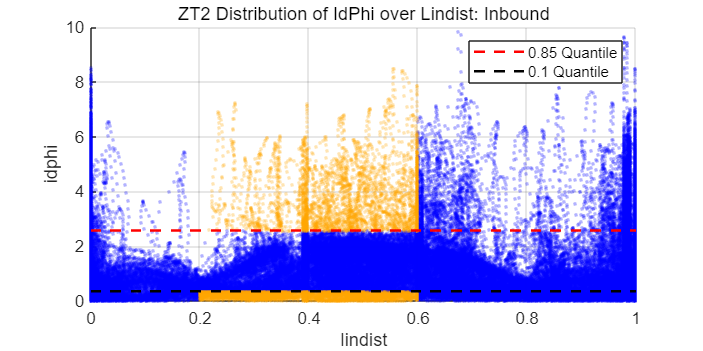


% 绘制散点图，根据条件设置颜色
scatter(plot_beh.lindist(~idx), plot_beh.idphi(~idx), 5, 'b', 'filled', 'MarkerFaceAlpha', 0.3); % 不符合条件的散点使用蓝色
hold on; % 保持在同一图形上绘制
scatter(plot_beh.lindist(idx), plot_beh.idphi(idx), 5, rgbColor, 'filled', 'MarkerFaceAlpha', 0.3); % 符合条件的散点使用红色
hold off; % 绘制完成后取消保持状态

ylim([0 10])

xlabel('lindist');
ylabel('idphi');
title('ZT2 Distribution of IdPhi over Lindist: Inbound');
grid on;


% 计算idphi的0.95和0.05分位数
q95 = quantile(plot_beh.idphi, 0.85);
q05 = quantile(plot_beh.idphi, 0.15);

% 在图上添加0.95和0.05分位数线
h1 = line([min(plot_beh.lindist), max(plot_beh.lindist)], [q95, q95], 'Color', 'r', 'LineStyle', '--', 'LineWidth', 1.5); % 使用红色粗虚线表示0.95分位数
h2 = line([min(plot_beh.lindist), max(plot_beh.lindist)], [q05, q05], 'Color', 'k', 'LineStyle', '--', 'LineWidth', 1.5); % 使用绿色粗虚线表示0.05分位数

legend([h1,h2],'0.85 Quantile', '0.1 Quantile');


%saveas(gcf, "F:\ComSub\Figures\multi_animals\ZT2 Distribution of IdPhi over Lindist_Inbound.pdf");


% 绘制idphi与lindist的散点图
plot_beh = behavior(behavior.vel> quantile(behavior.vel,0), :) ;
figure('Position', [100, 100, 800, 400]);

idx = (plot_beh.lindist >= 0.25+plot_beh.trajbound * 0.1) & (plot_beh.lindist <= 0.5 + plot_beh.trajbound * 0.1) &(plot_beh.idphi >= quantile(plot_beh.idphi,0.8)| plot_beh.idphi <= quantile(plot_beh.idphi,0.2));
disp(quantile(plot_beh.idphi, 0.1))

    0.2774



hexColor = '#FFA500';
rgbColor = (sscanf(hexColor(2:end), '%2x') / 255)'

rgbColor =     1.0000    0.6471         0


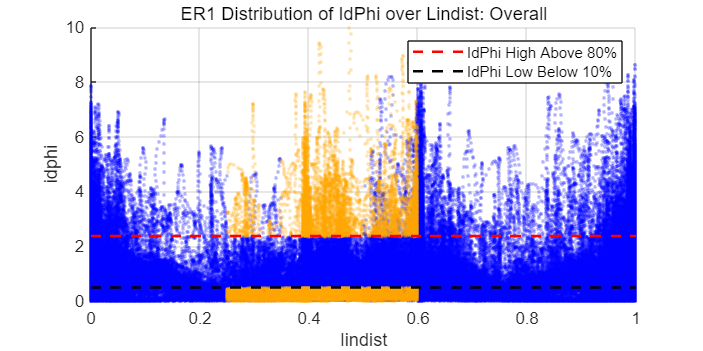


% 绘制散点图，根据条件设置颜色
scatter(plot_beh.lindist(~idx), plot_beh.idphi(~idx), 5, 'b', 'filled', 'MarkerFaceAlpha', 0.3); % 不符合条件的散点使用蓝色
hold on; % 保持在同一图形上绘制
scatter(plot_beh.lindist(idx), plot_beh.idphi(idx), 5, rgbColor, 'filled', 'MarkerFaceAlpha', 0.3); % 符合条件的散点使用红色
hold off; % 绘制完成后取消保持状态

ylim([0 10])

xlabel('lindist');
ylabel('idphi');
title('ER1 Distribution of IdPhi over Lindist: Overall');
grid on;


% 计算idphi的0.95和0.05分位数
q95 = quantile(plot_beh.idphi,0.8);
q05 = quantile(plot_beh.idphi,0.2);

% 在图上添加0.95和0.05分位数线
h1 = line([min(plot_beh.lindist), max(plot_beh.lindist)], [q95, q95], 'Color', 'r', 'LineStyle', '--', 'LineWidth', 1.5); % 使用红色粗虚线表示0.95分位数
h2 = line([min(plot_beh.lindist), max(plot_beh.lindist)], [q05, q05], 'Color', 'k', 'LineStyle', '--', 'LineWidth', 1.5); % 使用绿色粗虚线表示0.05分位数

legend([h1,h2],'IdPhi High Above 80%', 'IdPhi Low Below 10%');


%saveas(gcf, "F:\ComSub\Figures\multi_animals\ER1 Distribution of IdPhi over Lindist_Overall.pdf");


if ~exist('Option','var')
    disp("Option struct does not exist, creating one")
    addpath(genpath(codedefine()));
    Option = option.defaults(); 
else
    disp("Option struct already exists, using that")
    Option = option.setdefaults(Option);
    disp("Option struct is: ")
    disp(Option)
end

Option struct already exists, using that


Option struct is: 


                           animal: 'ZT2'
                     samplingRate: []
                     spikeBinSize: 0.0250
                          winSize: [-0.5000 0.5000]
          positiveDerivativeCheck: [0 0.1500]
       equalWindowsAcrossPatterns: 1
            quantileToMakeWindows: 0.8500
       thetadelta_outlierQuantile: [0 0.9950]
                   spikeShiftSize: 0.0100
                    timesPerTrial: 100
                       sourceArea: "CA1"
                 waysOfPartitions: 2
                    singleControl: 0
               oldControlBehavior: 0
                     lowerControl: 1
                    binsToMatchFR: 20
           preProcess_FilterLowFR: 1
    preProcess_matchingDiscreteFR: 1
        preProcess_gaussianFilter: 5
                preProcess_zscore: 1
                     numPartition: 40
                  dimCompAnalysis: 5
                       stablePerf: 0.9000
                        generateH: "fromSpectra  fromRipTimes"
                    



% Windowing parameters
Option.spikeBinSize = 0.025;    
Option.timesPerTrial = 50;
Option.winSize = [-0.5 0.5];
Option.preProcess_zscore = true;
Option.numPartition = 50;
Option.animal = "ZT2";




%%%%%%%%%%%%%%%% DISPLAY OUR OPTIONS TO USER %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%{
if isequal(Option.loadifexists, false) && ...
    exist(store.gethash(Option) + ".mat", 'file')
    disp("Loading from file: " + store.gethash(Option) + ".mat")
    m = matfile(store.gethash(Option) + ".mat");
    % m = matfile("bef0923.mat", "Writable", true);
    disp("Loaded variables: ")
    Events             = util.matfile.getdefault(m, 'Events', []);
    Spk                = util.matfile.getdefault(m, 'Spk', []);
    Patterns           = util.matfile.getdefault(m, 'Patterns', []);
    Patterns_overall   = util.matfile.getdefault(m, 'Patterns_overall', []);
    Components         = util.matfile.getdefault(m, 'Components', []);
    Components_overall = util.matfile.getdefault(m, 'Components_overall', []);
    Option             = util.matfile.getdefault(m, 'Option', []);
    disp("...done")
else
%}
    %%%%%%%%%%%%%%%% OBTAIN EVENT MATRICES    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Getting behavior
    [behavior, thrown_out_times] = table.behavior.lookup(Option.animal, ...
                                                         []);

Starting lookup for Z	Table with fields: time, vel, lindist, tperf_timewise, region, traj, trajbound, rewarded, X, Y, day, epoch

Converting to table:  000%  |                                          | 0/16 [00:00:00<Inf:NaN:NaN, Inf it/s]Throwing out times greater than 2 seconds away
Done with addToBehavior ... took 5.9491 seconds


    Events = events.initEvents();
    % Test case 1: TriggerOn when velocity (vel) exceeds a certain threshold
    Events = events.generateFromBehavior(behavior, {'rewardTimes'}, ...
        Events, 'triggerOnValues', {1}, ...
                'triggerOnVarnames', {'rewardTimes'}, ...
                'windowParameters',Option.winSize);

Triggering on rewardTimes = 1


    Events = events.generateFromBehavior(behavior, {'rewardTimes'}, ...
        Events, 'triggerOffValues', {1}, ...
                'triggerOffVarnames', {'rewardTimes'}, ...
                'windowParameters',Option.winSize);

Triggering off rewardTimes = 1


    qselect = @(x) (x.idphi > quantile(x.idphi, 0.8)) & (x.lindist > 0) & (x.lindist < 1);
    Events = events.generateFromBehavior(behavior, {'idphi'}, ...
        Events, 'triggerVarLambdas', {qselect}, ...
                'triggerVars', {'idphi'}, ...
                'maxWindows', 2000, ...
                'windowParameters',Option.winSize);

Triggering on idphi


    qselect2 = @(x) (x.idphi < quantile(x.idphi, 0.1)) & (x.lindist > 0) & (x.lindist < 1);
    Events = events.generateFromBehavior(behavior, {'idphi'}, ...
        Events, 'triggerVarLambdas', {qselect2}, ...
                'triggerVars', {'idphi'}, ...
                'maxWindows', 2000, ...
                'windowParameters',Option.winSize);

Triggering on idphi


    % Characterize events
    %figure; events.plot_events(Events, 'rewardTimes');
    % figure; events.plotIEI(Events, 'NumBins', 1000);
    %figure; events.plotCrossIEI(Events, 'NumBins', 1000, 'layout', 'matrix');
    Option.nPatternAndControl = numel(Events.cellOfWindows);
    Option.patternNames = ["rewardOn", "rewardOff","idphi","idphi_low"];


%%%%%%%%%%%%%%%% ACQUIRE SPIKES %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Getting spikes
    disp("------------------------")
    disp("    Getting spikes      ")
    disp("------------------------")
    Spk = spikes.getSpikeTrain(Option.animal, Option.spikeBinSize, ...
                               Option.samplingRate);
    % filter the neurons whose firing rate is lower than specified threshold
    if Option.preProcess_FilterLowFR 
        disp("------------------------")
        disp("Filtering low FR neurons")
        disp("------------------------")
        Spk = trialSpikes.filterFR(Spk, 0.1);
        disp("Mean FR: " + sort(Spk.avgFR))
    end
    if Option.preProcess_gaussianFilter
        % Gaussian filter the spikeCountMatrix/spikeRateMatrix
        gauss = gausswin(Option.preProcess_gaussianFilter);
        for i = progress(1:size(Spk.spikeRateMatrix, 1), 'Title', 'Gaussian filtering')
            Spk.spikeRateMatrix(i, :)  = conv(Spk.spikeRateMatrix(i, :), gauss, 'same');
            Spk.spikeCountMatrix(i, :) = conv(Spk.spikeCountMatrix(i, :), gauss, 'same');
        end
    end

    if Option.preProcess_zscore
        % Z-score the spikeCountMatrix/spikeRateMatrix
        disp(" Z-scoring ")
        if ~isfield(Spk, 'muFR')
            Spk.muFR  = mean(Spk.spikeRateMatrix, 2);
            Spk.stdFR = std(Spk.spikeRateMatrix, 0, 2);
        end
        Spk.spikeRateMatrix  = zscore(Spk.spikeRateMatrix,  0, 2);
        Spk.spikeCountMatrix = zscore(Spk.spikeCountMatrix, 0, 2);
        Spk.avgFR = mean(Spk.spikeRateMatrix, 2);
    end
    prewindow_copy = Spk;


% %%%%%%%%%%%%%% ACQUIRE TRIALS FROM WINDOWS + SPIKES %%%%%%%%%%%%%%%%%%%
    % RYAN bug here .. timeBinStartEnd instead of timeBinMidPoints
    disp("------------------------")
    disp("   Windowing spikes     ")
    disp("------------------------")
    Spk = trialSpikes.generate(Spk, Events, Option);

    %%%%%%%%%%%%%%%%% SETUP RAW DATA STRUCTURE %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Structure for separated data
    %%%%%%%%%%%%%%%% SEPRATE BRAIN AREA DATASULT STRUCTURES %%%%%%%%%%%%%%%%%%
    % Separate spikesSampleMatrix/Tensor by area that neurons are in PFC and
    % neurons that in HPC
     
    %% Separate firing pattern into source and target
    [Spk.nSource,~,~] = size(Spk.hpc.X{1});
    [Spk.nTarget,~,~] = size(Spk.pfc.X{1});
    Spk.celllookup = cellInfo.getCellIdentities(Option.animal, Spk.cell_index,...
                                                Spk.areaPerNeuron);
    system("pushover-cli 'Finished munging data for analysis'");

%%%%%%%%%%%%%%%% SETUP PARTITIONS AND RESULT STRUCTURES %%%%%%%%%%%%%%%%%%
    disp("------------------------")
    disp(" Subsampling partitions ")
    disp("------------------------")
    Option.numPartition = 40;
    [Patterns, Patterns_overall] = trialSpikes.partitionAndInitialize(Spk, Option);
    Components = nd.initFrom(Patterns, ...
    {'index_source', 'index_target', 'directionality', 'name'});
    Components_overall = nd.initFrom(Patterns_overall, ...
    {'index_source', 'index_target', 'directionality', 'name'});




Shifting

circshift

% 执行时间偏移并计算CCA
shift_values = -500:100:500; % 0ms, 100ms, ..., 500ms
values1 = cell(length(shift_values), 1);
values2 = cell(length(shift_values), 1);

% 获取X_time的起始时间
start_time = Patterns_overall(2,5).X_time(1);
Patterns_now = analysis.cca(Patterns_overall(2,5), Option);

for i = 1:length(shift_values)
    shift_time = shift_values(i);
    
    if shift_time >= 0
    relative_shift_time = start_time + (shift_time/1000);
    shift_points = find(Patterns_overall(2,5).X_time <= relative_shift_time, 1, 'last');
    shifted_source = circshift(Patterns_overall(2,5).X_source, [0, shift_points]);
    else
    relative_shift_time = start_time - (shift_time/1000);
    shift_points = find(Patterns_overall(2,5).X_time <= relative_shift_time, 1, 'last');
    shifted_source = circshift(Patterns_overall(2,5).X_source, [0, -shift_points]);
    end

    U = shifted_source' * Patterns_now.cca.a;
    V = (Patterns_overall(2,5).X_target)' * Patterns_now.cca.b;
    
    values1{i} = (U(:,1) + V(:,1))/sqrt(2);
    values2{i} = (U(:,1) - V(:,1))/sqrt(2);
end

Running CCA analysis...


CCA analysis completed in 2.5608 s
Running CCA analysis...


CCA analysis completed in 2.5742 s
Running CCA analysis...


CCA analysis completed in 3.5315 s
Running CCA analysis...


CCA analysis completed in 2.5202 s
Running CCA analysis...


CCA analysis completed in 2.746 s
Running CCA analysis...


CCA analysis completed in 2.4281 s


lindist_now = interp1(behavior.time, behavior.directional_lindist, Patterns_overall(2,5).X_time, 'linear');

% 绘制U值
coolwarm = [
  0.230, 0.299, 0.754;  % Dark blue
  0.865, 0.865, 0.865;  % Light gray
  0.706, 0.016, 0.150  % Dark red
];
% 定义插值的x坐标
x = linspace(1, 11, 3);
% 定义目标的x坐标
new_x = 1:11;
% 对每个颜色通道进行插值
r = interp1(x, coolwarm(:,1), new_x);
g = interp1(x, coolwarm(:,2), new_x);
b = interp1(x, coolwarm(:,3), new_x);

% 合并结果
cm = [r', g', b'];


% 将cell向量堆叠到一个大矩阵中
matrixData = cell2mat(values1);

% 计算均值向量
meanVector = mean(matrixData, 1);

% 从每个向量中减去均值向量
normalizedData = bsxfun(@minus, matrixData, meanVector);

% 将结果存储回cell数组中
values1 = mat2cell(normalizedData, ones(1, size(normalizedData, 1)), size(normalizedData, 2));



figure;

% 创建一个空的图形句柄数组来存储循环中的图形句柄
h_plots = gobjects(1, 11);

for i = 1:11
    h_plots(i) = plot(Patterns_overall(2,5).X_time, values1{i,1}, 'DisplayName', [num2str(shift_values(i)), 'ms'], 'Color', [cm(i,:)]);
    hold on;
end

h = plot(Patterns_overall(2,5).X_time, lindist_now, 'DisplayName', "lindist", "LineWidth", 2); % 使用plot绘制线条
% 获取线条的XData和YData
xd = get(h, 'XData');
yd = get(h, 'YData');
% 使用patch函数设置线条的透明度
patch('XData', xd, 'YData', yd, 'EdgeColor', [0 0 1 0.5], 'FaceColor', 'none', 'LineWidth', 2);

xlabel('Time (s)');
ylabel('values1');
title('values for different time shifts');

% 仅使用循环中的图形句柄创建图例
legend(h_plots, 'Location', 'best');

yline(0);


ans = 0.2302

Visualizing Spike Data

% 示例数据
X_source = Patterns_overall(2,3).X_source;
X_target = Patterns_overall(2,3).X_target;

% Heatmap for X_source
figure;
imagesc(X_source);
xlabel('Time');
ylabel('Neuron #');
title('Heatmap for X-source');
caxis([0 30])
colorbar;

% Heatmap for X_target
figure;
imagesc(X_target);
xlabel('Time');
ylabel('Neuron #');
title('Heatmap for X-target');
caxis([0 30])
colorbar;


% 合并X_source和X_target
X_source = Patterns_overall(2,3).X_source; % 假设数据是正态分布的
X_target = Patterns_overall(2,3).X_target;
combined_data = [X_source; X_target];

% 执行PCA
[coeff, score, ~] = pca(combined_data);

% 2D PCA plot
figure;
scatter(score(1:size(X_source, 1), 1), score(1:size(X_source, 1), 2), 'r', 'filled'); % X_source in red
hold on;
scatter(score(size(X_source, 1)+1:end, 1), score(size(X_source, 1)+1:end, 2), 'b', 'filled'); % X_target in blue
xlabel('PC1');
ylabel('PC2');
title('2D PCA Visualization');
legend('X-source', 'X-target');

% 3D PCA plot
figure;
scatter3(score(1:size(X_source, 1), 1), score(1:size(X_source, 1), 2), score(1:size(X_source, 1), 3), 'r', 'filled'); % X_source in red
hold on;
scatter3(score(size(X_source, 1)+1:end, 1), score(size(X_source, 1)+1:end, 2), score(size(X_source, 1)+1:end, 3), 'b', 'filled'); % X_target in blue
xlabel('PC1');
ylabel('PC2');
zlabel('PC3');
title('3D PCA Visualization');
legend('X-source', 'X-target');


JPECC

warning("off","all")
a1 = size(Spk.hpc.T{1,1});
a2 = size(Spk.hpc.T{1,2});
a3 = size(Spk.hpc.T{1,3});
a4 = size(Spk.hpc.T{1,4});
trial = [a1(3),a2(3),a3(3),a4(3)];

disp("------------------------")
disp("        jpecc           ")
disp("------------------------")

Option.analysis.JPECC = 1;


%tJ_Patterns = analysis.JPECC(Patterns, Option, 1, trial);
%tJ_Patterns2 = analysis.JPECC(Patterns, Option, 2, trial);
tJ_Patterns3 = analysis.JPECC(Patterns, Option, 3, trial);
tJ_Patterns4 = analysis.JPECC(Patterns, Option, 4, trial);


%{
stackedMatrices = cell(1, 40);
for i = 1:40
    x = nd.fieldGet(tJ_Patterns(i).jpecc, "val1");
    stackedMatrices{1,i} = x;
end
stackedMatrice = cat(40, stackedMatrices{1,:});
meanMatrix = nanmean(stackedMatrice, 40);

stackedMatrices2 = cell(1, 40);
for i = 1:40
    x = nd.fieldGet(tJ_Patterns2(i).jpecc, "val1");
    stackedMatrices2{1,i} = x;
end
stackedMatrice2 = cat(40, stackedMatrices2{1,:});
meanMatrix2 = nanmean(stackedMatrice2, 40);
%}
stackedMatrices3 = cell(1, 40);
for i = 1:40
    x = nd.fieldGet(J_Patterns3.JS21(i).jpecc, "val1");
    stackedMatrices3{1,i} = x;
end
stackedMatrice3 = cat(40, stackedMatrices3{1,:});
meanMatrix3 = nanmean(stackedMatrice3, 40);

%{
stackedMatrices4 = cell(1, 40);
for i = 1:40
    x = nd.fieldGet(tJ_Patterns4(i).jpecc, "val3");
    stackedMatrices4{1,i} = x;
end
stackedMatrice4 = cat(40, stackedMatrices4{1,:});
meanMatrix4 = nanmean(stackedMatrice4, 40);
%}

J_Patterns3

J_Patterns3 = 包含以下字段的 struct :
    JS14: [1×40 struct]


stackedMatrices3p = cell(1, 40);

threshold = 0.05;
significant_ratio_threshold = 0.9;


P = J_Patterns3.JS21;
for i = 1:40
    x = nd.fieldGet(P(i).jpecc, "p1");
    stackedMatrices3p{i} = x;
end
stackedMatrice3p = cat(40, stackedMatrices3p{:});
    
% 计算每个单元格中p值小于阈值的比例
significance_ratio = sum(stackedMatrice3p < threshold, 40) / 40;
    
combined_significance = significance_ratio > significant_ratio_threshold;


sigma = 1;
filter_size = 3;
[x, y] = meshgrid(-filter_size:filter_size, -filter_size:filter_size);
h = exp(-(x.^2 + y.^2) / (2 * sigma^2));
h = h / sum(h(:));  % normalize the filter

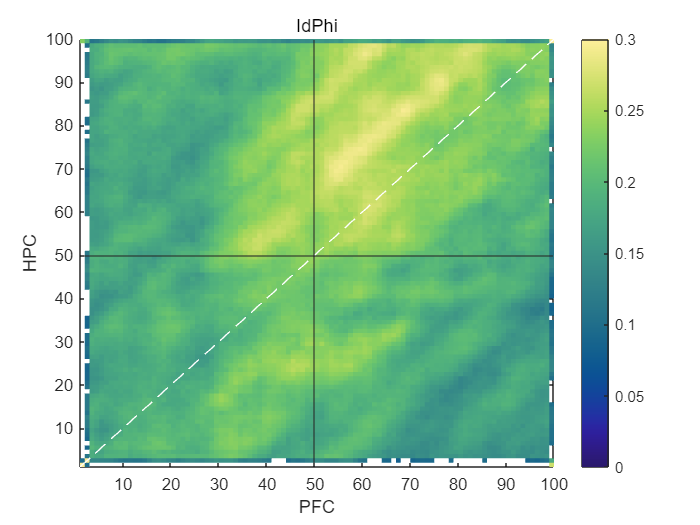

lindist_trajbound = meanMatrix3;
indist_trajbound = conv2(lindist_trajbound, h, 'same');
lindist_trajbound(combined_significance == 0) = NaN;

% heatmap
figure;
t = pcolor(lindist_trajbound);
%shading interp;

caxis([0 0.3]);
cmocean('haline')
colorbar

%{
%caxis([-0.4 0.4]);
colormap(cmap);
colorbar;
%}

set(t, 'EdgeColor', 'none');
line([1 100], [1 100], 'Color', [1,1,1], 'LineWidth', 0.8,"LineStyle", "--");
xline(50)
yline(50)

xlabel('PFC');
ylabel('HPC');
title('IdPhi');
saveas(gcf, "F:\ComSub\Figures\multi_animals\idphi and reward\IdPhi-JS21-Outbound-dim1" + ".pdf");